# Zonotope Bundle

In CORA, zontope bundles are instantiated by 

% zB = zonoBundle(list);

where `list` is a list (cell-array) of zonotope objects.

Example:

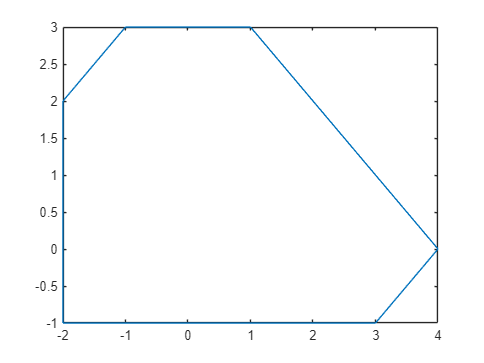

% initialize zonotopes
Z1 = zonotope([1;1],[3 0; 0 2]);
Z2 = zonotope([0;0],[2 2; 2 -2]);

% initialize zonotope bundle
list = {Z1,Z2};
zB = zonoBundle(list);

% plot zonotope bundle
plot(zB);

For more information, type

help zonoBundle

  zonoBundle - object constructor for zonotope bundles
 
  Description:
     This class represents zonotope bundle defined as
     \bigcap_j=1^k {c_j + \sum_{i=1}^p_j beta_i * g_j^(i) | beta_i \in [-1,1]},
     i.e., the intersection of k zonotopes
 
  Syntax:
     obj = zonoBundle(list)
 
  Inputs:
     list - cell-array list = {Z1,Z2,...} storing the zonotopes that
            define the zonotope bundle
 
  Outputs:
     obj - zonoBundle object
 
  Example:
     Z1 = zonotope([1 3 0; 1 0 2]);
     Z2 = zonotope([0 2 2; 0 2 -2]);
     zB = zonoBundle({Z1,Z2});
 
     figure; hold on;
     plot(zB,[1,2],'FaceColor','r');
     plot(Z1,[1,2],'b');
     plot(Z2,[1,2],'g');
 
  References:
     [1] M. Althoff. "Zonotope bundles for the efficient computation of 
         reachable sets", 2011
 
  Other m-files required: none
  Subfunctions: none
  MAT-files required: none
 
  See also: 